clc; clear;

% Sample signal
N = 36;                 % number of samples
t = linspace(0,1,N);     
x = 3*cos(2*t) + 5*sin(9*t);

% DFT
X = fft(x)/N;            % normalize

% Frequency index
k = 1:N/2-1;

% Harmonic coefficients (real form)
a0 = 2*real(X(1));       % DC term

b = 2*real(X(2:N/2));    % cosine coefficients
a = -2*imag(X(2:N/2));   % sine coefficients

% Display first few harmonics
disp('b0 ='); disp(a0)

b0 =
    4.8104



disp('b_k ='); disp(a(1:10))

b_k =
    1.7935    0.4238    0.3474    0.2643    0.2087    0.1695    0.1402    0.1173    0.0985    0.0827



disp('a_k ='); disp(b(1:10))

a_k =
    3.7549   -2.5302   -0.6266   -0.2679   -0.1290   -0.0595   -0.0195    0.0056    0.0224    0.0340




% Power spectrum
P = abs(X(1:N/2)).^2;

figure;

subplot(3,1,1)
stem(k, b, 'filled')
title('Cosine Coefficients a_k')
xlabel('Harmonic k')
ylabel('b_k')
grid on

subplot(3,1,2)
stem(k, a, 'filled')
title('Sine Coefficients b_k')
xlabel('Harmonic k')
ylabel('a_k')
grid on

subplot(3,1,3)
stem(0:N/2-1, P, 'filled')
title('Power Spectrum |X(k)|^2')
xlabel('Harmonic k')
ylabel('Power')
grid on



prob2

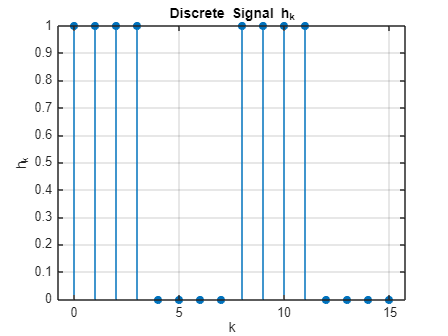

clc; clear; close all;

%% Parameters
N = 16;
fs = 1;                 % Sampling frequency (Hz)
k = 0:N-1;              % Sample index
t = k;                  % since Δ = 1 sec

%% (a) Construct h_k
h = zeros(1,N);

h(1:4)   = 1;   % k = 0..3
h(5:8)   = 0;   % k = 4..7
h(9:12)  = 1;   % k = 8..11
h(13:16) = 0;   % k = 12..15

% Plot discrete signal
figure;
stem(k, h, 'filled');
title('Discrete Signal h_k');
xlabel('k'); ylabel('h_k');
grid on;


%% (b) Frequency parameters
fmax = fs/2;
df = fs/N;

fprintf('fmax = %.3f Hz\n', fmax);

fmax = 0.500 Hz


fprintf('Delta f = %.5f Hz\n', df);

Delta f = 0.06250 Hz


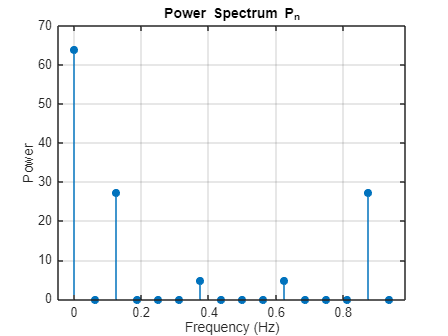


%% (c) DFT computation
H = fft(h);

% Frequency axis
f = (0:N-1)*(fs/N);

%% (d) Power spectrum
P = abs(H).^2;

%% (e) Plot power spectrum
figure;
stem(f, P, 'filled');
title('Power Spectrum P_n');
xlabel('Frequency (Hz)');
ylabel('Power');
grid on;

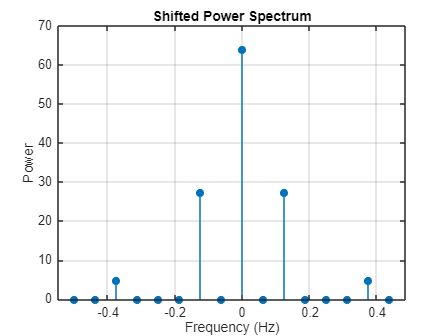


%% Optional: Shifted spectrum (better visualization)
figure;
f_shift = (-N/2:N/2-1)*(fs/N);
P_shift = fftshift(P);

stem(f_shift, P_shift, 'filled');
title('Shifted Power Spectrum');
xlabel('Frequency (Hz)');
ylabel('Power');
grid on;


%% (f) Harmonic coefficients (Fourier series form)

% Normalize (since your H = fft(h) is NOT normalized)
X = H / N;

% DC term
a0 = 2*real(X(1));

% Harmonic indices
n = 1:N/2-1;

% Coefficients
an = 2*real(X(1:N/2));     % cosine terms
bn = -2*imag(X(1:N/2));    % sine terms

% Display
disp('a0 ='); disp(a0)

a0 =
     1



disp('a_n ='); disp(an)

a_n =
    1.0000         0    0.2500         0         0         0    0.2500         0



disp('b_n ='); disp(bn)

b_n =
         0         0    0.6036         0         0         0    0.1036         0

